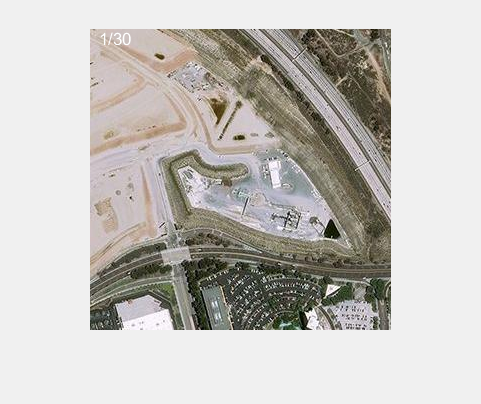

clc
clear all
close all

letter = "B";
directory = "Test Images/Snipped/"+letter+"/";
imagefiles = dir(directory);      
nfiles = length(imagefiles);    % Number of files found

% figure()
for ii=4:nfiles
   currentfilename = imagefiles(ii).name;
   currentimage = imread(directory+currentfilename);
   images{ii - 3} = currentimage;
   [~,imageNames{ii - 3},~] = fileparts(currentfilename);
   % subplot(nfiles-3, 1, ii - 3);
   % imshow(images{ii - 3});
end

neworder = randperm(length(images));
for i=1:length(images)
    images2{i} = images{neworder(i)};
end
images = images2;

% images{1} = imread("Test Images/Snipped/A/A4.jpg");
% images{2} = imread("Test Images/Snipped/A/A7.jpg");
% images{3} = imread("Test Images/Snipped/A/A15.jpg");
% images{4} = imread("Test Images/Snipped/A/A12.jpg");
% images{5} = imread("Test Images/Snipped/A/A18.jpg");

% images{1} = imread("leftoriginal.png")
% images{2} = imread("leftleft.png")

% % right = imread("leftshifted.png");
% figure()
% imshow(images{1})
% imshow(images{2})

fig = figure;
set(gcf,'Visible','on');

out = images{1};
thresh = 0.0007;
speedthresh = 0.01;
stitched = zeros(length(images),1);
stitched(1)=1;
length(images);

pltanim(out,stitched);

     1



    0.0105



ans = 0.4398

    0.0636



ans = 0.8273

    0.0516



ans = 0.3452

    0.0129



ans = 0.6462

    0.3275



ans = 0.6689

    0.0230



ans = 0.6062

    0.0331



ans = 0.6356

    0.2623



ans = 0.6203

    0.0145



ans = 0.8503

    0.0318



ans = 0.8705

    0.0228



ans = 0.7550

    0.2864



ans = 0.7449

    0.0106



ans = 0.5454

    0.0017



ans = 0.7538

    0.0023



ans = 0.5026

    0.0446



ans = 0.3916

    0.0069



ans = 0.2946

default_points = 1.2500

     2



   7.2400e-04



ans = 0.6056

    0.0514



ans = 0.6742

    0.0018



ans = 0.6552

    0.0600



ans = 0.7238

    0.0308



ans = 0.5702

    0.0077



ans = 0.3951

    0.0070



ans = 0.3566

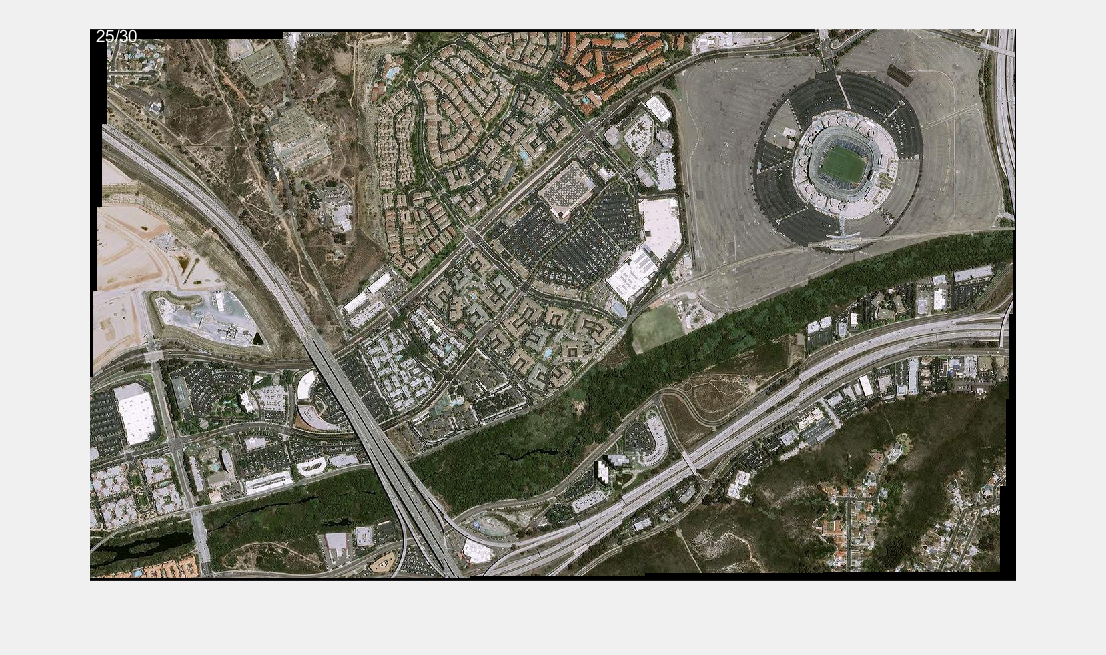

default_points = 1.7500

     3



default_points = 2.2500

     4




end_early = false;
default_points = 0.75;
for j=1:length(images)
    disp(j)
    points=default_points;
    finished = false;
    while ~finished
        confidences = zeros(length(images),3);
        for i=1:length(images)
            if stitched(i)==0
                [final_slope, final_length, final_delta_x, final_delta_y, final_confidence] = custom_sift(out, images{i}, 8, points, true);
                confidences(i,:)=[final_confidence,final_delta_x,final_delta_y];
                if confidences(i,1)>=speedthresh
                    break
                end
            end
        end
        if sum(confidences(:,1)>=thresh)~=0
            [v,ind]=max(confidences(:,1));
            disp(v)
            [out, valid] = merge_images(out, images{ind}, round(-confidences(ind,2)), round(-confidences(ind,3)));
            % imwrite(out, "Output/"+letter+"/Run3_Stitch"+sum(stitched)+"_Conf"+round(v*10000)+".jpg");
            if ~valid
                points=points+0.5
            else
                stitched(ind)=1;
                pltanim(out,stitched);
            end
        else
            finished=true;
            end_early=true;
        end
    end
    if end_early
        if default_points<2
            default_points=default_points+0.5
        else
            break
        end
    end
end

sum(stitched)

ans = 25

imageNames(~stitched)

ans = 1×5 cell array
    {'B12'}    {'B27'}    {'B30'}    {'B4'}    {'B7'}


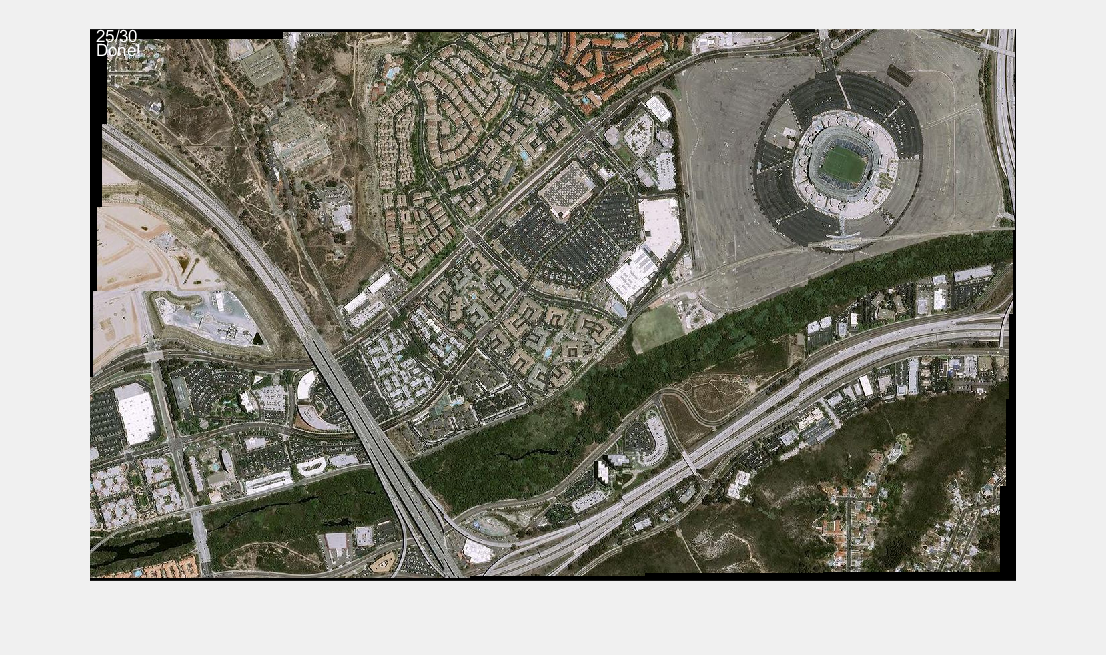

pltanim(out,stitched);
text(10,30,"Done!","Color",[1,1,1]);

function [] = pltanim(out, stitched)
        imshow(out);
        text(10,10,""+sum(stitched)+"/"+length(stitched),"Color",[1,1,1]);
        drawnow();
end